close("all"); clear; clc;

vx = 80/3.6;
k = 0;
p = bikeSimToSharp(bigSportsParameters());
sys = sharpMotorcycleStateSpaceFactory(vx,p);

a = [
    0,vx;
    -vx*k^2,0
    ];

A = [
    a,zeros(2),eye(2),zeros(2,4);
    zeros(8,2),sys.a
    ];

B = [
    zeros(2,1);
    sys.b
    ];

C = blkdiag(eye(2),sys.c);

D = 0;

sys = linearSys(A,B,[],C);

params.tFinal = 1;
params.R0 = zonotope(zeros(10,1),zeros(10,1));
params.U = zonotope(interval(-50,50));

options.timeStep = 0.01;
options.zonotopeOrder = 40;
options.taylorTerms = 10;

R = reach(sys,params,options);

x_max = [
    3.5;
    deg2rad(90);
    deg2rad(45);
    deg2rad(90);
    5;
    pi;
    pi;
    2*pi;
    1E06;
    1E06
    ];

Zmax = interval(-x_max,x_max);

fS = @(R)vertices(project(polytope(reduce(R,'girard') & Zmax),1:3));
S = cellfun(fS,R.timePoint.set(2:end),"uniform",0);
t = R.timePoint.time(2:end);

fC = @(t,S)contactPoint(t,S(1,:));
C = cellfun(fC,t.',S.',"uniform",0);

fG = @(C,S)massCenter(C,dcm(S(2,:),S(3,:)));
G = cellfun(fG,C,S.',"uniform",0);

pC = cell2mat(C);
pG = cell2mat(G);

P = cellfun(@(c,g)[c,g],C,G,"uniform",0);

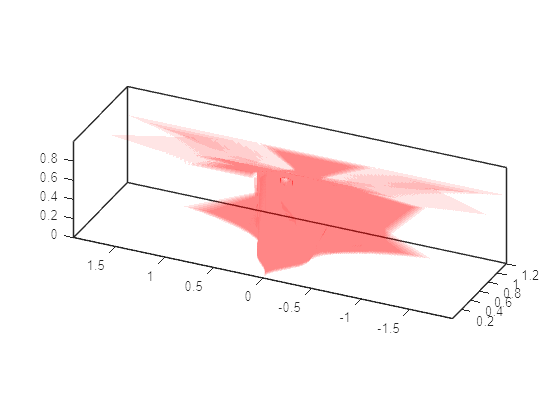

fig = figure();
axe = axes(fig);
view(axe,3);
hold(axe,"on");
fP = @(p)fill3(p(1,:),p(2,:),p(3,:),'r', ...
    "FaceAlpha",0.1, ...
    "EdgeColor","none");
cellfun(fP,P)
hold(axe,"off");
zlim(axe,[0,2]);
box(axe,"on");
axis(axe,"equal");

function C = contactPoint(s,d)
    arguments
        s (1,1) double;
        d (1,:) double;
    end
    C = [
        zeros(size(d)) + s;
        d;
        zeros(size(d))
        ];
end

function R = dcm(rel_head,lean)
    arguments
        rel_head (1,:) double;
        lean (1,:) double;
    end
    rh = reshape(rad2deg(rel_head),1,1,[]);
    l = reshape(rad2deg(lean),1,1,[]);
    f = @(rh,l)rotz(rh)*rotx(l);
    R = cell2mat(arrayfun(f,rh,l,"uniform",0));
end

function G = massCenter(C,R)
    arguments
        C (3,:) double;
        R (3,3,:) double;
    end
    I = repmat(eye(3,3),1,1,size(R,3));
    e0 = repmat([0,0,0].',1,1,size(R,3));
    e3 = repmat([0,0,1].',1,1,size(R,3));
    e4 = repmat([0,0,0,1],1,1,size(R,3));
    pC = reshape(C,3,1,[]);

    T0 = [
        I,pC;
        e4
        ];

    T1 = [
        R,e0;
        e4
        ];

    T2 = [
        I,e3;
        e4
        ];

    T = pagemtimes(pagemtimes(T0,T1),T2);
    G = squeeze(T(1:3,4,:));
end